# Calcolo Numerico con Laboratorio

# Prova in Laboratorio 

# 17 gennaio 2022

## Istruzioni

- Svolgere gli esercizi aggiungendo il codice nel file LIveScript con il testo degli esercizi oppure usando file di tipo Script.

- Se si usa il file Live Script le figure risultano automaticamente allegate.

- Se si lavora con file di tipo script, salvare le figure in formato .fig.

- Non usare il comando `input.`

- Eventuali commenti richiesti, devono essere scritti come testo nel file LiveScript.

- Caricare **tutti **i file usati (comprese le function prodotte durante le esercirazioni che servono per svolgere gli esercizi) e le figure richieste sul sito di elearning.

- Dopo aver aperto Matlab, dare il comando **diary** prima di cominciare a lavorare e ripetere questo comando tutte le volte che si riavvia Matlab. Il comando diary registra tutto quello che viene fatto durante la prova.

## Esercizio 1

Si consideri la funzione $f(x)=e^{-2x^2+1}\frac{\sin(2x-1)+2}{\cos(x)+1.2}$ per $x\in[-3,3]$.

Per `n=2:12`, eseguire le seguenti operazioni:

1. Interpolare la funzione nell'intervallo assegnato con i polinomi di grado `n`, costruiti usando $n+1$ nodi di Chebyshev e $n+1$ punti equidistanti .

2. Usando il comando subplot riportare 3 grafici contenenti rispettivamente: 

- la funzione e il polinomio interpolatore con nodi equidistanti;

- la funzione e il polinomio interpolatore con nodi di Chebyshev;

- la funzione e i due polinomi interpolatori.

3. Calcolare per ciascun valore di $n$ l'errore commesso usando i polinomi con nodi equidistanti e con nodi di Chebyshev.

4. Riportare gli errori per i due polinomi in uno stesso grafico in scala semilogaritmica.

grado del polinomio 2


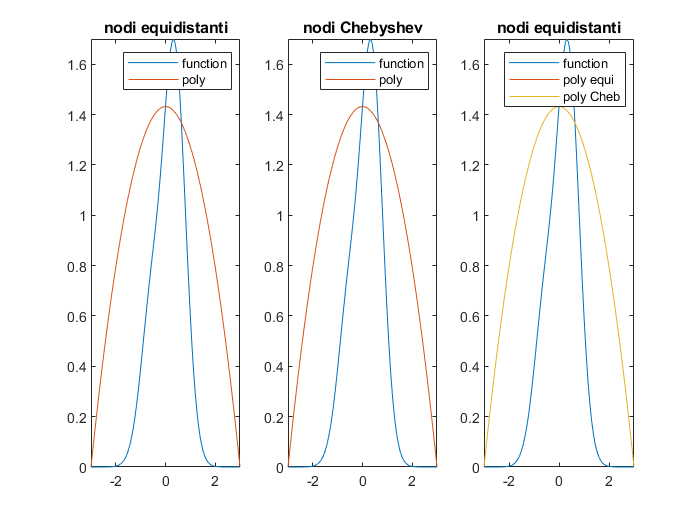

grado del polinomio 3


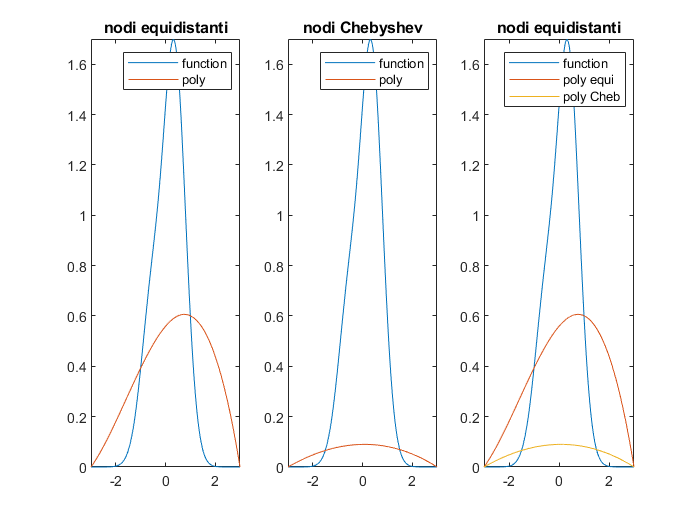

grado del polinomio 4


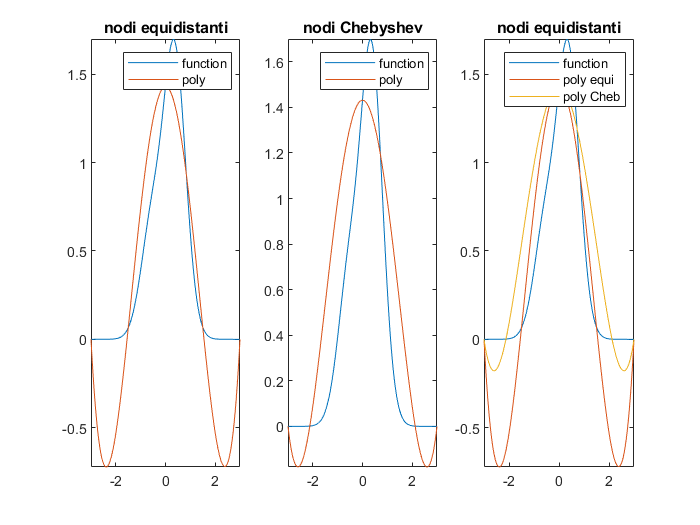

grado del polinomio 5


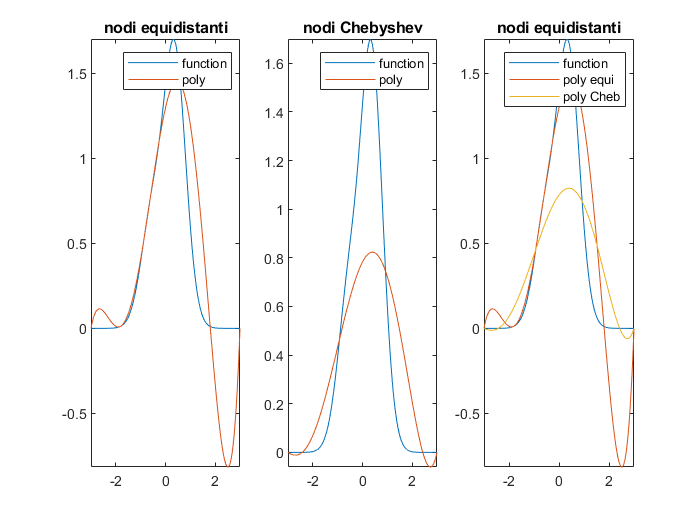

grado del polinomio 6


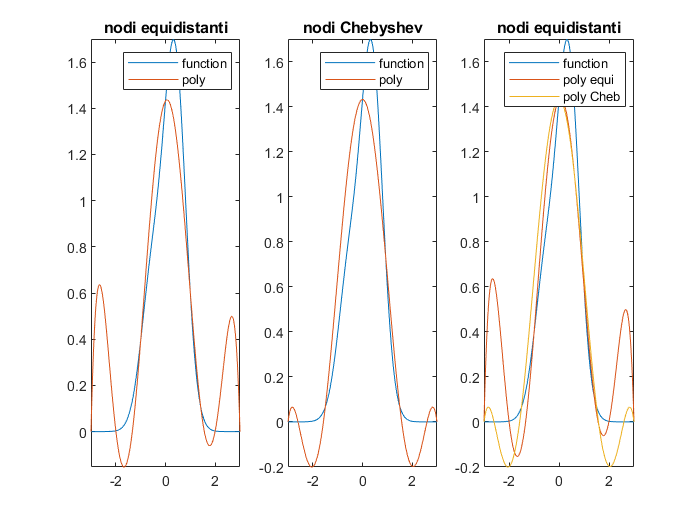

grado del polinomio 7


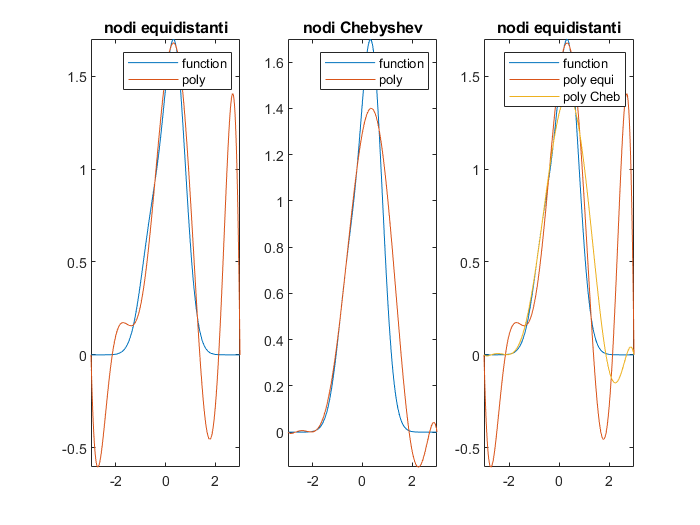

grado del polinomio 8


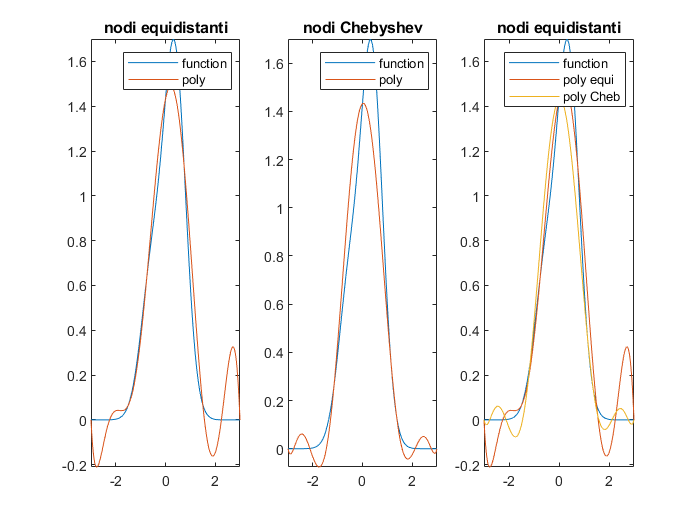

grado del polinomio 9


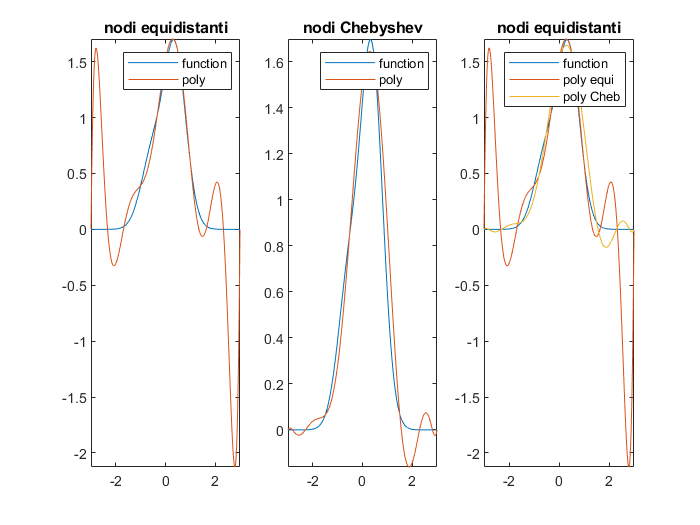

grado del polinomio 10


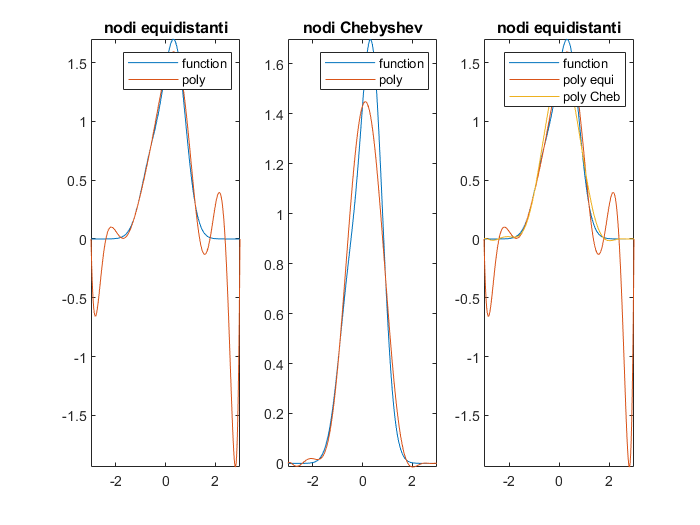

grado del polinomio 11


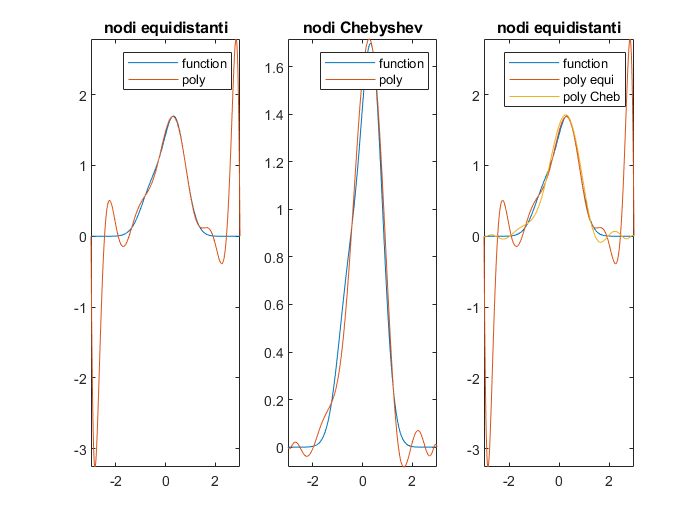

grado del polinomio 12


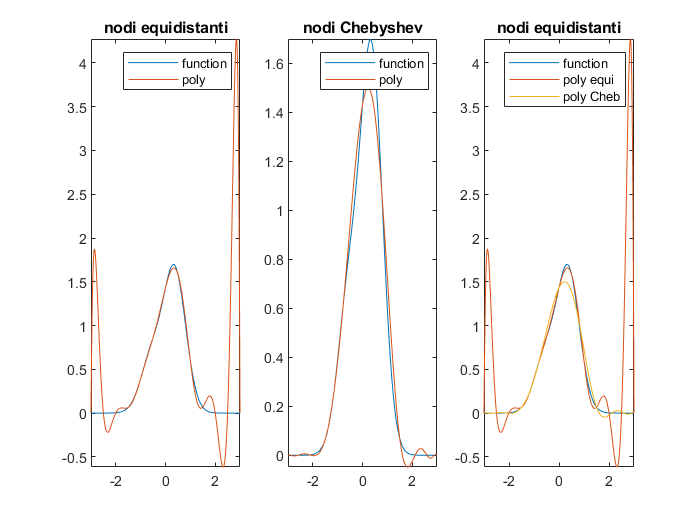

clear all
close all
f=@(x) exp(-2*x.^2+1).*(sin(2*x-1)+2)./(cos(x)+1.2);
intx=[-3 3];
E=[];Ec=[];
z=linspace(intx(1),intx(2),12*100);
for n=2:12
    [p,y,x,err]=calcPoly(f,intx,n);
    [pc,xc,yc,errc]=chebyshev(n,intx(1),intx(2),f);
    disp("grado del polinomio "+n)
    figure
    subplot(1,3,1)
    fplot(f,intx)
    hold on
    plot(z,polyval(p,z))
    title("nodi equidistanti")
    legend("function","poly")
    subplot(1,3,2)
    fplot(f,intx)
    hold on
    plot(z,polyval(pc,z))
    title("nodi Chebyshev")
    legend("function","poly")
    subplot(1,3,3)
    fplot(f,intx)
    hold on
    plot(z,polyval(p,z))
    plot(z,polyval(pc,z))
    title("nodi equidistanti")
    legend("function","poly equi","poly Cheb")
    E=[E err];
    Ec=[Ec errc];    
end

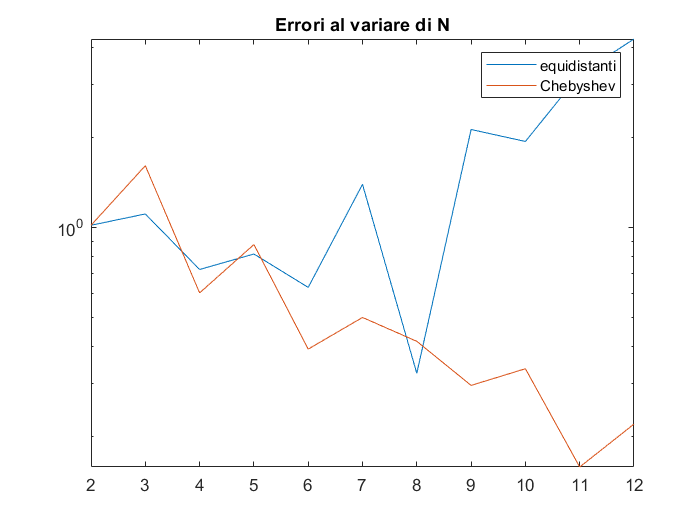

figure
semilogy(2:12,E)
hold on
semilogy(2:12,Ec)
title("Errori al variare di N")
legend("equidistanti","Chebyshev")

Esercizio 2

Usare la function `newton `e il solutore di Matlab `fzero `per calcolare gli zeri della seguente funzione:

$f(x)=2\arctan(x)+\sin(2x)(x^2-1)-\cos(x)+1$ per $x\in[-\pi,\pi]$.

Usare i seguenti dati iniziali `x0=[-1 1 2 3],`e porre `toll=1e-10` e `nmax=50 `nella function `newton.`

- Fare un grafico della funzione e riportare sul grafico tutti gli zeri calcolati con i due metodi (marcare gli zeri di Newton con * e quelli di fzero con o).

- Per ciascun dato iniziale riportare la successione generata con il metodo di Newton.

- Riportare in un unico grafico in scala semilogaritmica la differenza fra due iterate successive ottenute con il metodo di Newton e commentare il risultato.

- Per visualizzare meglio quanto ottenuto in corrispondenza dei primi due dati iniziali, fare un ingrandimento della funzione con gli zeri corrispondenti nell'intervallo $[-0.3,0.3]$. 

- Osservando il grafico della soluzione, qual è la molteplicità degli zeri?

- `newton` ed `fzero `convergono allo stesso valore?

- Qual è l'ordine di convergenza del metodo di Newton in ciascun caso?  

Rispondere agli ultimi tre punti utilizzando il file LiveScript del compito oppure aggiungendo dei commenti sul file di tipo Script.

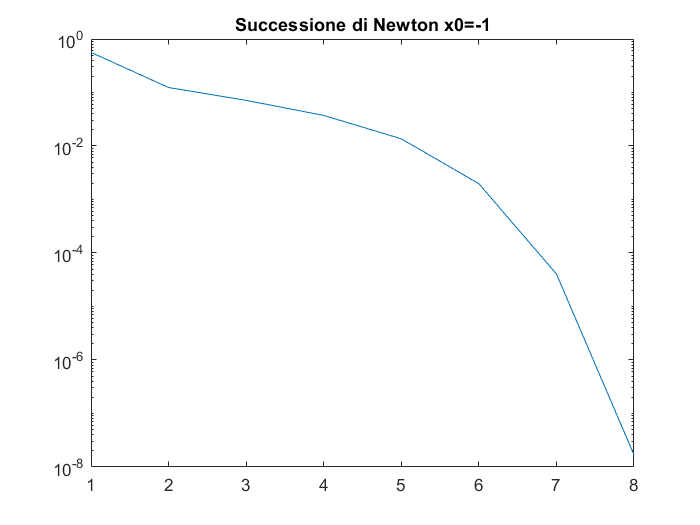

per x0=-1 si trova uno zero:-0.19002 e si ha uno zero singolo
ordine di convergenza 2


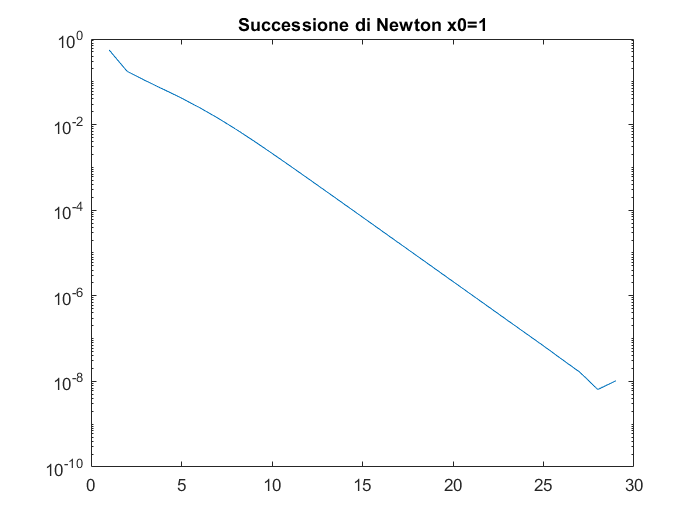

per x0=1 si trova uno zero:3.1208e-10 e si ha uno zero doppio
ordine di convergenza 1


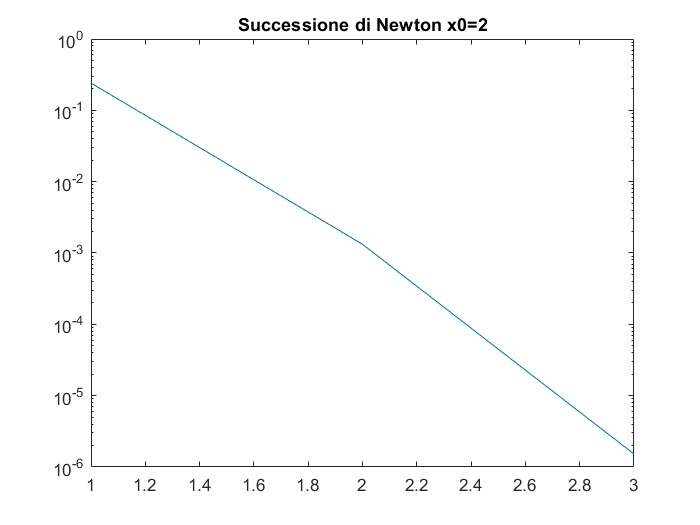

per x0=2 si trova uno zero:2.2425 e si ha uno zero singolo
ordine di convergenza 2


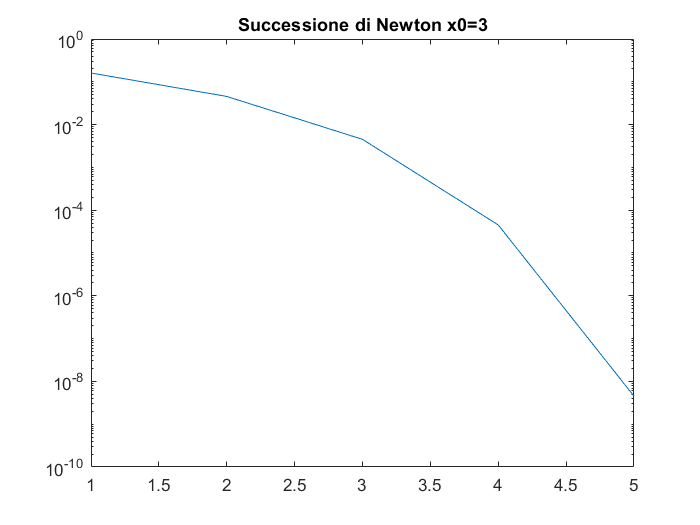

per x0=3 si trova uno zero:2.7893 e si ha uno zero singolo
ordine di convergenza 2


clear all
close all
syms x;
f=2*atan(x)+sin(2*x)*(x^2-1)-cos(x)+1;
df=matlabFunction(diff(f));
intx=[-pi,pi];toll=1e-10;nmax=50;
Xn=[];Xf=[];Yn=[];Yf=[];
for x0=[-1 1 2 3]
    [zn,fvn,itern,xkn]=newton(f,x0,toll,nmax);
    [zf,fvf]=fzero(matlabFunction(f),x0);
    Xn=[Xn zn'];
    Xf=[Xf zf'];
    Yn=[Yn fvn'];
    Yf=[Yf fvf'];
    figure
    semilogy(abs(xkn(1:end-1)-xkn(2:end)))
    title("Successione di Newton x0="+x0)
    ordineConv(df,x0,zn)
end

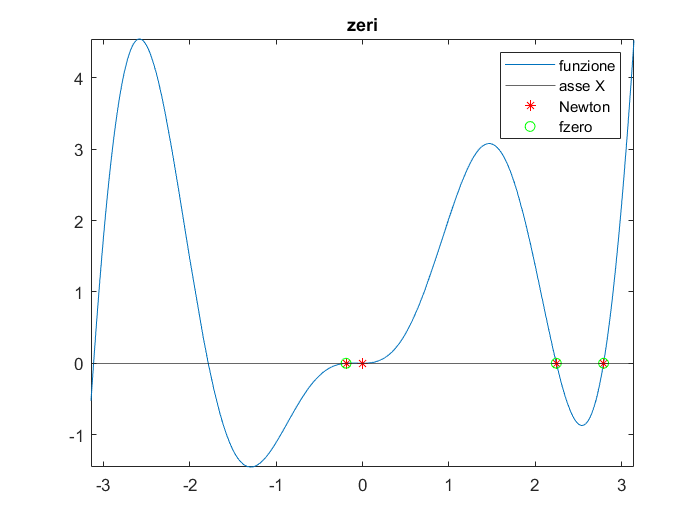

figure
fplot(f,intx)
hold on
yline(0)
plot(Xn,Yn,'*r')
plot(Xf,Yf,'og')
title("zeri")
legend("funzione","asse X","Newton","fzero")

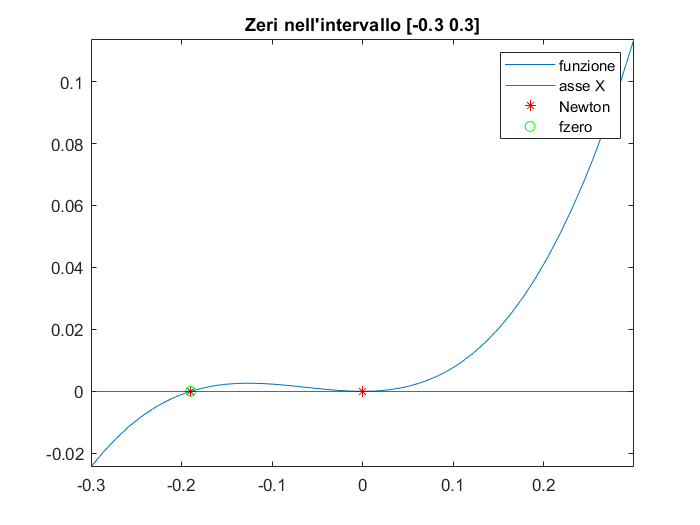

figure
fplot(f,[-0.3 0.3])
hold on
yline(0)
plot(Xn(1:2),Yn(1:2),'*r')
plot(Xf(1:2),Yf(1:2),'og')
title("Zeri nell'intervallo [-0.3 0.3]")
legend("funzione","asse X","Newton","fzero")

Nel caso dei primi due zeri trovati (punti di partenza x0=[-1 1]) la funzione Newton riesce ad individuare lo zero presente in x = 3.1208e-10 mentre invece la funzione fzero non riesce e questo perchè vi sono due zeri vicini e quello in questione è uno zero doppio e quindi più difficile da individuare.

Non per tutti i valori di x0 il metodo di Newton e fzero convergono nello stesso valore e questo per via del fatto che adottano algoritmi di ricerca differenti.

## Esercizio 3

Consideriamo il seguente sistema di equazioni differenziali ordinarie:


$$\left\{
\begin{array}{l}
y_1'=a(y_2-y_1)\\
y_2'=ry_1-y_2-y_1y_3\\
y_3'=-by_3+y_1y_2
\end{array}
\right.

$$


dove $a$, $b$ e $r$ sono delle costanti positive legate a quantità fisiche. Questo sistema rappresenta un modello semplificato della turbolenza atmosferica la cui derivazione può essere così sintetizzata: una cella bidimensionale verticale di aria viene riscaldata dal basso e raffreddata dall'alto e il risultante movimento viene descritto da un sistema di equazioni alle derivate parziali. Sviluppando in serie le variabili e approssimandole opportunamente si giunge al sistema dato. La variabile $y_1$ rappresenta il tasso di ricircolazione convettiva, $y_2$ e $y_3$  misurano la variazione di temperatura lungo l'orizzontale e lungo la verticale rispettivamente. 

Questo sistema presenta soluzioni che per alcuni dati iniziali hanno un andamento caotico. Inoltre il sistema ha 3 punti di equilibrio: $O=(0,0,0)$, $P_1=(c,c,r-1)$ e $P_2=(-c,-c,r-1)$ dove $c=\sqrt{b(r-1)}$. Posto $r_{rc}=a(a+b+3)/(a-b-1)$, $P_1$ e $P_2$ sono asintoticamente stabili se $r<r_{rc}$ e instabili se $r>r_{rc}$.

Posto $a=10$, $b=8/3$ e `toll=1e-10 `$r=70$, verificare se la soluzione deve risultare stabile oppure no. Calcolare con `ode45 `la soluzione del sistema nell'intervallo $[0,20]$ con la condizione iniziale $y_0=(1,1,1)$.

Riportare le tre componenti in un grafico in funzione del tempo e successivamente usare il comando `plot3` per graficare l'orbita ottenuta. Nel grafico dell'orbita marcare anche i punti di equilibrio.

Calcolare la soluzione nello stesso intervallo di tempo ponendo $r=r_{rc}-1$ e con i seguenti dati iniziali $y_0=(1,1,1)$ e $y_0=(-1,1,1)$e riportare i risultati in un grafico in funzione del tempo e l'orbita corrispondente insieme ai punti di equilibrio. Si osserva che a seconda del dato iniziale le orbite si addensano attorno a $P_1$ o a $P_2$.

clear all
close all
int=[0 20];a=10;b=8/3;r=70;y0=[1;1;1];toll=1e-10;
y1=@(y) a*(y(2)-y(1));
y2=@(y) r*y(1)-y(2)-y(1).*y(3);
y3=@(y) -b*y(3)+y(1).*y(2);
Y=@(t,y) [y1(y);y2(y);y3(y)];
rcr=a*(a+b+3)/(a-b-1);
if r < rcr
    disp("Sistema stabile")
else
    disp("Sistema instabile")
end

Sistema instabile


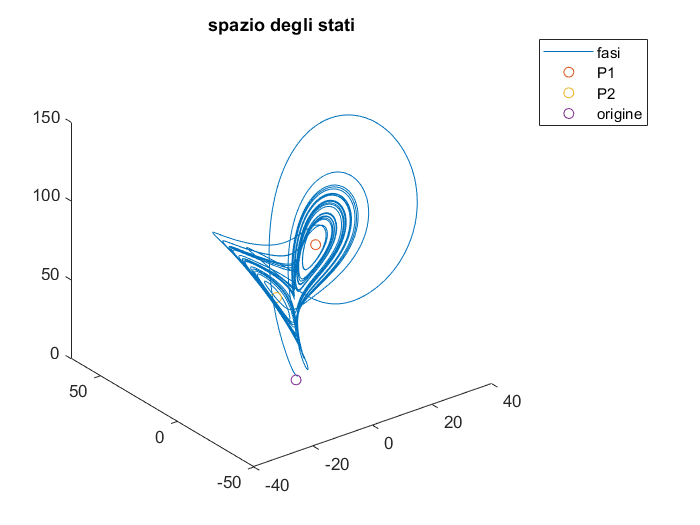

opt=odeset('RelTol',toll);
[t,u]=ode45(Y,int,y0,opt);
plot3(u(:,1),u(:,2),u(:,3))
hold on
c=sqrt(b*(r-1));
P1=[c;c;r-1];P2=[-c;-c;r-1];O=[0;0;0];
plot3(P1(1),P1(2),P1(3),'o')
plot3(P2(1),P2(2),P2(3),'o')
plot3(O(1),O(2),O(3),'o')
title("spazio degli stati")
legend("fasi","P1","P2","origine")

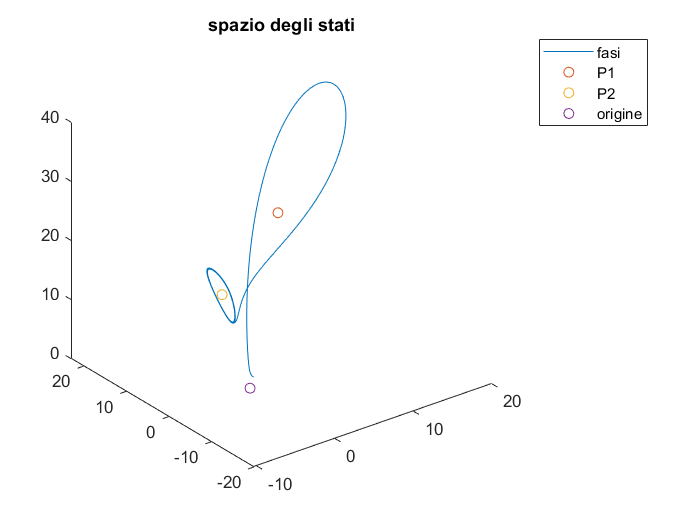

clear all
int=[0 20];a=10;b=8/3;y0=[1;1;1];toll=1e-10;
rcr=a*(a+b+3)/(a-b-1);
r=rcr-1;
y1=@(y) a*(y(2)-y(1));
y2=@(y) r*y(1)-y(2)-y(1).*y(3);
y3=@(y) -b*y(3)+y(1).*y(2);
Y=@(t,y) [y1(y);y2(y);y3(y)];
opt=odeset('RelTol',toll);
[t,u]=ode45(Y,int,y0,opt);
figure
plot3(u(:,1),u(:,2),u(:,3))
hold on
c=sqrt(b*(r-1));
P1=[c;c;r-1];P2=[-c;-c;r-1];O=[0;0;0];
plot3(P1(1),P1(2),P1(3),'o')
plot3(P2(1),P2(2),P2(3),'o')
plot3(O(1),O(2),O(3),'o')
title("spazio degli stati")
legend("fasi","P1","P2","origine")

Nel caso di y0 = (1,1,1) il sistema orbita attorno al punto P2.

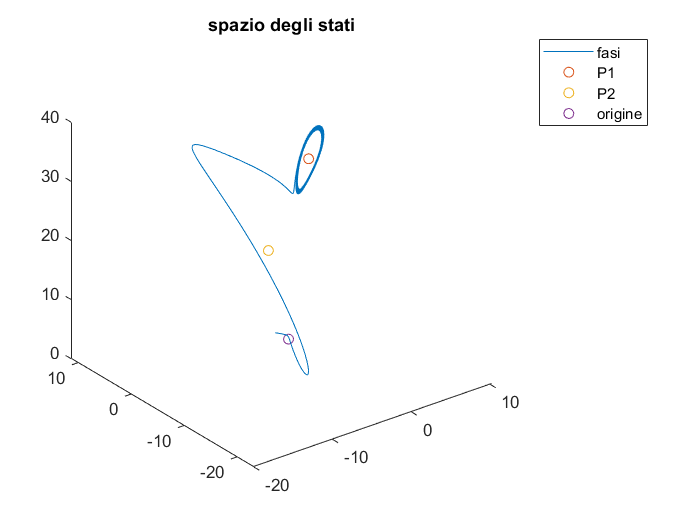

clear all
int=[0 20];a=10;b=8/3;y0=[-1;1;1];toll=1e-10;
rcr=a*(a+b+3)/(a-b-1);
r=rcr-1;
y1=@(y) a*(y(2)-y(1));
y2=@(y) r*y(1)-y(2)-y(1).*y(3);
y3=@(y) -b*y(3)+y(1).*y(2);
Y=@(t,y) [y1(y);y2(y);y3(y)];
opt=odeset('RelTol',toll);
[t,u]=ode45(Y,int,y0,opt);
figure
plot3(u(:,1),u(:,2),u(:,3))
hold on
c=sqrt(b*(r-1));
P1=[c;c;r-1];P2=[-c;-c;r-1];O=[0;0;0];
plot3(P1(1),P1(2),P1(3),'o')
plot3(P2(1),P2(2),P2(3),'o')
plot3(O(1),O(2),O(3),'o')
title("spazio degli stati")
legend("fasi","P1","P2","origine")

Nel caso di y0 = (1,1,1) il sistema orbita attorno al punto P1.